**Exercise 5**

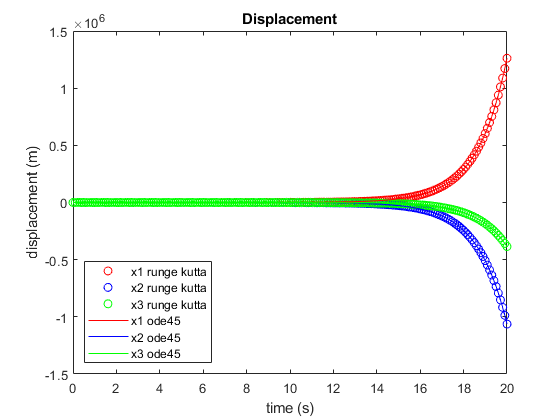

initialcond = [0; 0; 0; 1; 0; 0;]; % initial conditions
t=linspace(0,20,200);
func = @odesyst;
[a b]=ode45(func,t,initialcond);
ode45x1 = b(:,1);
ode45x2 = b(:,2);
ode45x3 = b(:,3);
ode45velx1 = b(:,4);
ode45velx2 = b(:,5);
ode45velx3 = b(:,6);


[result]=runge_kutta(func,t,initialcond);
x1 = result(1,:);
x2 = result(2,:);
x3 = result(3,:);
velx1 = result(4,:);
velx2 = result(5,:);
velx3 = result(6,:);

plot(t,x1,'ro',t,x2,'bo',t,x3,'go',t,ode45x1,'r',t,ode45x2,'b',...
    t,ode45x3,'g')
title('Displacement');
xlabel('time (s)');
ylabel('displacement (m)');
legend('x1 runge kutta','x2 runge kutta','x3 runge kutta',...
    'x1 ode45','x2 ode45','x3 ode45','Location','southwest')

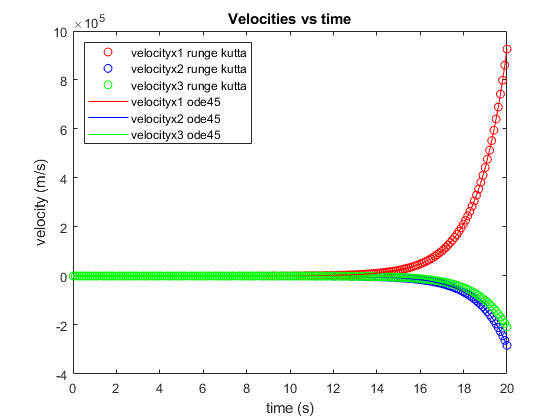


plot(t,velx1,'ro',t,velx2,'bo',t,velx3,'go',t,ode45velx1,'r',t,ode45velx2,'b',...
    t,ode45velx3,'g')
title('Velocities vs time');
xlabel('time (s)');
ylabel('velocity (m/s)');
legend('velocityx1 runge kutta','velocityx2 runge kutta','velocityx3 runge kutta',...
    'velocityx1 ode45','velocityx2 ode45','velocityx3 ode45','Location','northwest')

We can also make a graph of the absolute value of the velocities, since we already know the direction of the displacements by the first graph:

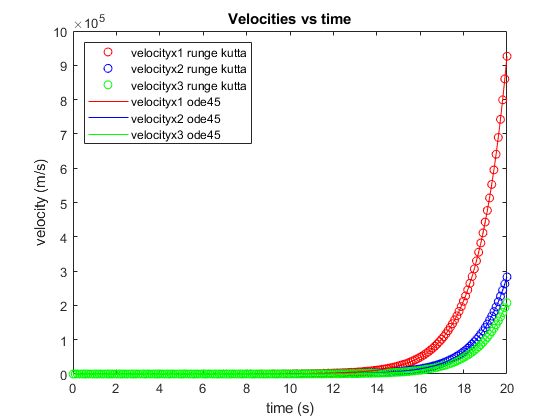

plot(t,abs(velx1),'ro',t,abs(velx2),'bo',t,abs(velx3),'go',t,abs(ode45velx1),'r',t,abs(ode45velx2),'b',...
    t,abs(ode45velx3),'g')
title('Velocities vs time');
xlabel('time (s)');
ylabel('velocity (m/s)');
legend('velocityx1 runge kutta','velocityx2 runge kutta','velocityx3 runge kutta',...
    'velocityx1 ode45','velocityx2 ode45','velocityx3 ode45','Location','northwest')

function [dydt] = odesyst(t,y)

k1=3000; k2=2400; k3=1800;
m1=12000; m2=10000; m3=8000;

x1=y(1);x2=y(2);x3=y(3);
dydt=zeros(6,1);

dydt(1) = y(4); %dx1/dt
dydt(2) = -(k1/m1)*x1+(k2/m1)*(x2-x1); %d^2x1/dt^2

dydt(3) = y(5); % dx2/dt
dydt(4) = (k2/m2)*(x1-x2)+(k3/m2)*(x3-x2); %d^2x2/dt^2

dydt(5) = y(6); % dx3/dt
dydt(6) = (k3/m3)*(x2-x3); % d^2x3/dt^2
end



function [y] = runge_kutta(df,x,y0)
m = length(y0);
n = length(x);
% y is a matrix of size 'mxn'
y=zeros(m,n);
y(:,1)=y0;
for i=1:n-1
    h = x(i+1)-x(i);
    xi=x(i);
    yi=y(:,i);
    k1 = feval(df,xi,yi);
    k2 = feval(df,xi+0.5*h,yi+0.5*k1*h);
    k3 = feval(df,xi+0.5*h,yi+0.5*k2*h);
    k4 = feval(df,xi+h,yi+k3*h);
    y(:,i+1) = y(:,i) + h*(k1+2*k2+2*k3+k4)/6;
end
end
